# Monte Carlo

Monte Carlo techniques refer to a large suite of methods that use random numbers to solve problems. 

## Error Propagation

We can calculate formulae for error propagation using partial differentiation, but sometimes the resulting equations are unwieldly and the derivation sufficiently complicated that mistakes are easily made. Instead, if we make assumptoins about the probability distribution functions of our measured variables, we can use a Monte Carlo simulation to estimate the errors on the value we are interested in. For example, if we measure the pressure, temperature and volume of a gas, we can use the Ideal Gas Law to calculate the number of moles (N) of gas that are present. If we know the means and standard deviations of the measured variables, then we can calculate umber of possible values that all fit those distributions and which we can use to calculate N, find its mean and standard deviation. We have to make an assumption about the distributions that measured variables obey, and in this case we will assume that they are all normal distribution, but this might not always be the case.

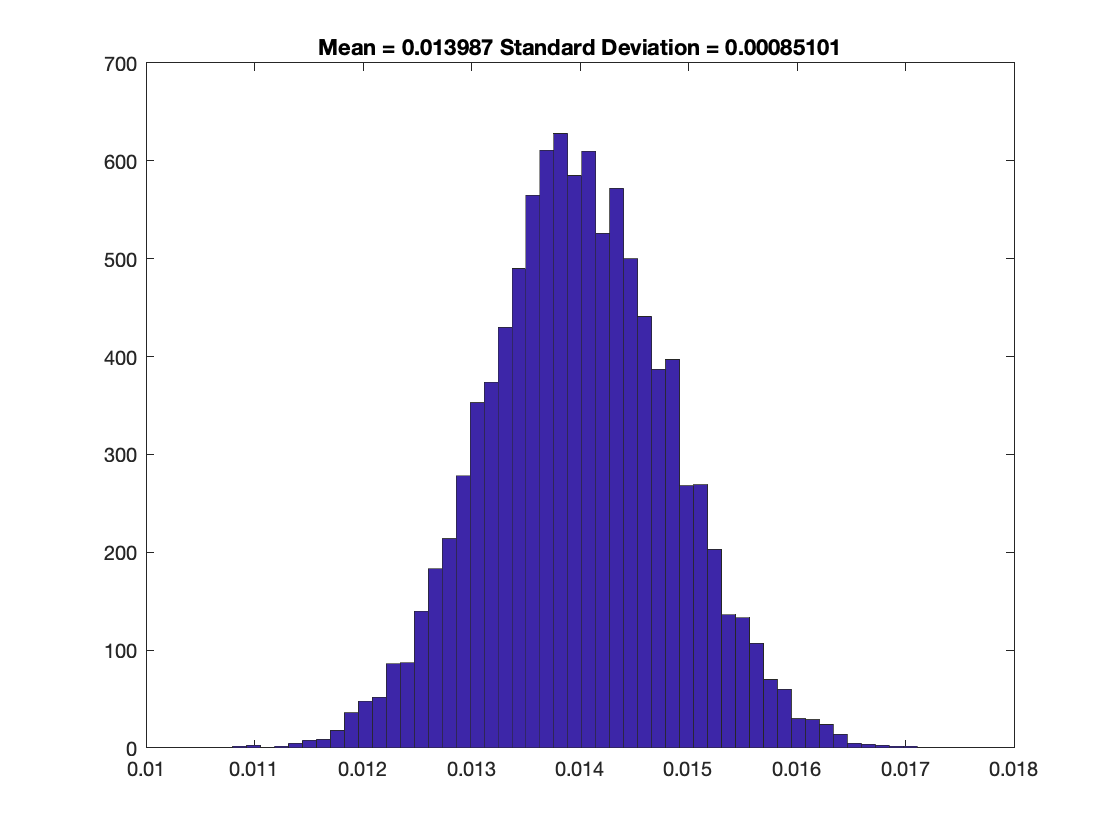

% First set the number of samples that we want to use. This should be quite
% large so that we can get reliable statistics. 
n_samples = 10000;

% Define the variables in the equation   
r = 0.082;    % The Gas Constant

p_mean = 0.268;  % The pressure mean and standard deviation
p_std  = 0.012;

v_mean = 1.26;   % The volume mean and standard deviation
v_std  = 0.05;

t_mean = 294.2;  % The temperature mean and standard deviation
t_std  = 0.3;

% Now generate n_samples of each of these variables using the measured
% means and standard deviations and assuming that they all obey normal
% distributions.
p = p_mean + p_std*randn([n_samples, 1]);
v = v_mean + v_std*randn([n_samples, 1]);
t = t_mean + t_std*randn([n_samples, 1]);

% Use the Gas Law to calculate the number of moles for each sample
n_moles = p .* v ./ (r * t);

% Calculate the mean and standard deviation of the resulting distribution
n_mean = mean(n_moles);
n_std   = std(n_moles);

% Plot the distribution of values of N
figure(1)
hist(n_moles, 50)
title(['Mean = ' num2str(n_mean) ' Standard Deviation = ' num2str(n_std)])

As we can see, for a complicated formula it can be far easier to calculate error propagation estimates using a Monte Carlo simulation.

***Exercise:**** Investigate what happens to the accuracy of the error propagation for a small number of samples (e.g. *`n_samples = 10`*). Gradually increase the number of samples and see how many samples it takes before you get an answer that does not change. *

***Exercise:**** Monte Carlo error propagation can also be useful for cases where the calculus method no longer holds. Consder for example a case where the uncertainties in the measured variables in the gas law example are high (e.g. 40–50% of the mean value) and perform a Monte Carlo analysis. Compare your answers to those you get from using a calculus method. *

## Monte Carlo Integration

Monte Calro simulation techniques can also be used to calculate difficult integrals. We will demonstrate the basic technique using some simple integrals that we can evaluate by hand so that we can compare the answers. We will start with a simple exponential function. As explained in Chapter 5, there are several Monte Carlo techniques we can use. We will start by just a simple method and see how quickly the value converges to the exact value as the number of samples we use increases.   

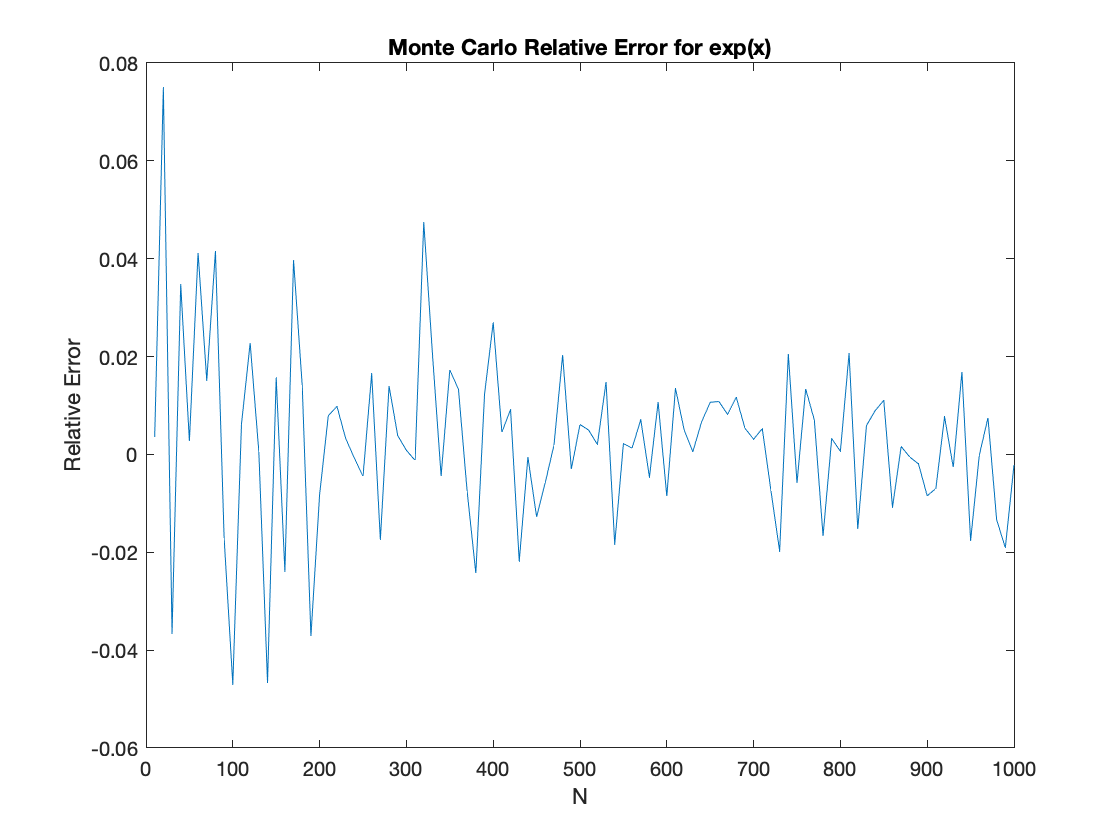

% The number of experiments, each with a different number of samples
n_expts = 100;

% Monte Carlo integration of exp(x) on [a,b]
a = 2;
b = 3;
exact_value = exp(b) - exp(a);

% Preallocate storage
N_value   = zeros(n_expts,1);  % The number of samples
I_value   = zeros(n_expts,1);  % The value of the integral
Err_value = zeros(n_expts,1);  % the error

% Start the loop to estimate the integral using different numbers of
% samples. We want to increase the number of samples quire rapidly, so we
% get the number of samples by multiplying the expeirment number by 10
for i_count = 1 : n_expts
    
    N_value(i_count) = i_count * 10;
    
    % Calculate a random value of x between the limits of integeration
    % using a uniform distribution
    x = a + (b-a)*rand(N_value(i_count),1);
    
    mc_sum = sum(exp(x));
    
    I_value(i_count)   = (b-a) * mc_sum / N_value(i_count);
    Err_value(i_count) = (I_value(i_count) - exact_value)/exact_value;
end

figure(2)
plot(N_value, Err_value)
xlabel('N')
ylabel('Relative Error')
title('Monte Carlo Relative Error for exp(x)')

As you can see, we get a good estimate quite quickly, although there is still some variability even for 1000 samples. 

***Exercise:**** Investigate what happens using fewer or more samples. *

*We will now evaluate a different integral but using the above method and a simpler one. In this case we will integrate*


$$\int_0^1 \sin^2\left(\frac{1}{x}\right)\, dx$$


First we will try the simpler hit-or-miss method where we throe down random points and count the proportion that fall between the function and the x-axis. 

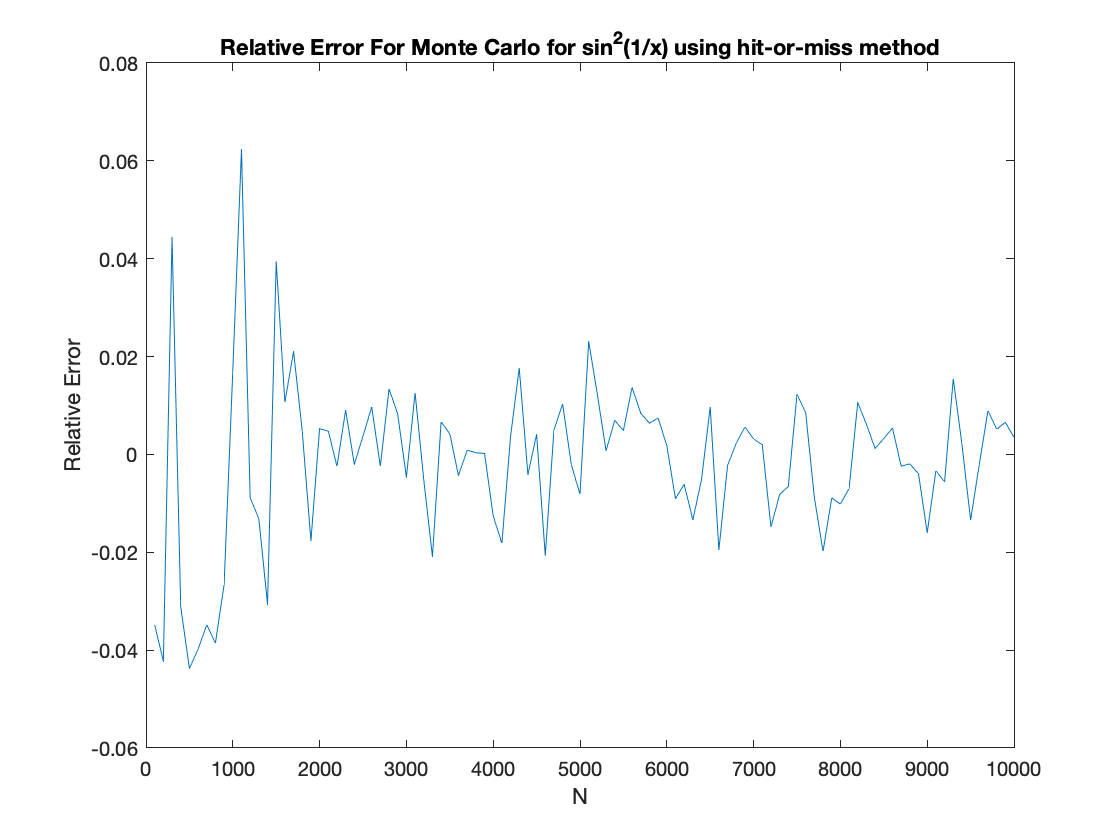

% Set the limits of the integral and the function maximum. 
a     = 0;
b     = 1;
f_max = 1;

exact_value = 0.6734568;

% Preallocate storage
N1_value   = zeros(100, 1);
I1_value   = zeros(100, 1);
Err1_value = zeros(100, 1);

for i_count = 1 : 100
    
    N1_value(i_count) = i_count * 100;
   
    x = rand(N1_value(i_count), 1);
    y = rand(N1_value(i_count), 1);
    
    yf = (sin(1./x)).^2;
    
    N0 = length(find(y < yf));    
    I1_value(i_count) = N0/N1_value(i_count);
    Err1_value(i_count) = (I1_value(i_count) - exact_value)/exact_value;
    
end

figure(3)
plot(N1_value, Err1_value)
xlabel('N')
ylabel('Relative Error')
title('Relative Error For Monte Carlo for sin^2(1/x) using hit-or-miss method')

Use the other method

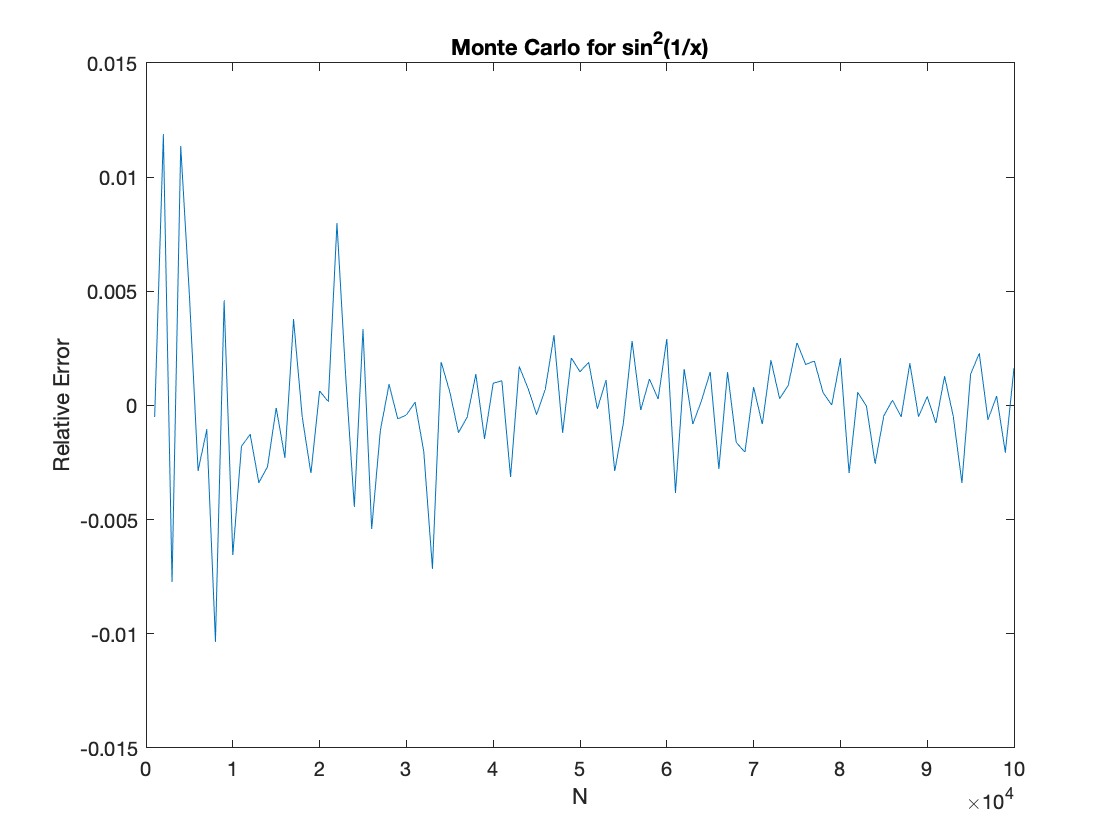

% Preallocate storage
N2_value   = zeros(100, 1);
I2_value   = zeros(100, 1);
Err2_value = zeros(100, 1);

for i_count = 1 : 100
    
    N2_value(i_count) = i_count * 1000;
    
    x = a + (b-a)*rand(N2_value(i_count),1);
    
    mc_sum = sum((sin(1./x)).^2);
    
    I2_value(i_count) = (b-a) * mc_sum / N2_value(i_count);
    Err2_value(i_count) = (I2_value(i_count) - exact_value)/exact_value;
end

figure(4)
plot(N2_value, Err2_value)
xlabel('N')
ylabel('Relative Error')
title('Monte Carlo for sin^2(1/x)')

Because Monte Carlo techniques depend on random numbers, each time the simulation is run you will get slightly different results, but if you use a large enough number of samples, you will always converge to the value of the integral. 